clear all;

### Параметры

% alpha= [-1, -3, -4, -4];
% beta= [ 0.5, 0.5, 2, 1];
% gamma= [ 0.1, 4, 9, 4];
% 
% delta = [0.5, 0.5, 0.5, 0.5];
alpha= [-0.2, -0.4, -0.5, -0.8];
beta= [ 0, 0.1, 0.2, 0.2];
gamma= [ 0.1, 4, 9, 4];

delta = [1, 1, 1, 1];

s = 2; damp = 1.36; mode = 2;
numExp = 50;

### Тестирование

[T1,Y1] = TestEquastionROCK(alpha(1), beta(1), gamma(1), delta(1), s,damp, mode, numExp);
[T2,Y2] = TestEquastionROCK(alpha(2), beta(2), gamma(2), delta(2), s,damp, mode, numExp);
[T3,Y3] = TestEquastionROCK(alpha(3), beta(3), gamma(3), delta(3), s,damp, mode, numExp);
[T4,Y4] = TestEquastionROCK(alpha(4), beta(4), gamma(4), delta(4), s,damp, mode, numExp);

### Графики

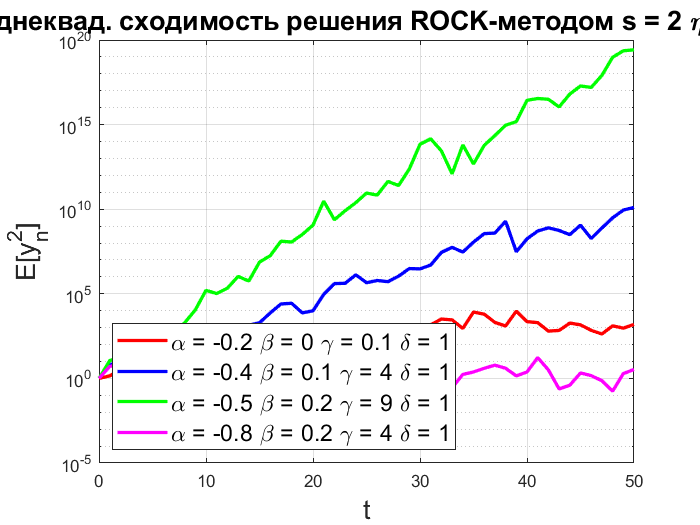

figure
semilogy(T1, Y1 , "red",'LineWidth',2);
hold on
grid on
semilogy(T2, Y2 , "blue",'LineWidth',2);
semilogy(T3, Y3 , "green",'LineWidth',2);
semilogy(T4, Y4 , "magenta",'LineWidth',2);
title(['Среднеквад. сходимость решения ROCK-методом' [' s = ' num2str(s)] [' \eta = ' num2str(damp)]], "FontSize",16);
xlabel("t", "FontSize",16);
ylabel("E[y_n^2]", "FontSize",16);
legend([['\alpha = ' num2str(alpha(1))] [' \beta = ' num2str(beta(1))] [' \gamma = ' num2str(gamma(1))] [' \delta = ' num2str(delta(1))]], ...
    [['\alpha = ' num2str(alpha(2))] [' \beta = ' num2str(beta(2))] [' \gamma = ' num2str(gamma(2))] [' \delta = ' num2str(delta(2))]], ...
    [['\alpha = ' num2str(alpha(3))] [' \beta = ' num2str(beta(3))] [' \gamma = ' num2str(gamma(3))] [' \delta = ' num2str(delta(3))]], ...
    [['\alpha = ' num2str(alpha(4))] [' \beta = ' num2str(beta(4))] [' \gamma = ' num2str(gamma(4))] [' \delta = ' num2str(delta(4))]], ...
    "FontSize",14, "Location","southwest");